clear all;
close all;
clc;

# HOUSEKEEPING DATA

Load the data

currentFolder = pwd;
cd('C:/Users/PC/OneDrive/Documentos/Systems_Biology_master/Internship/Internship/Data');
data = readtable("data_TPM.xlsx");
h_k_g = readtable('NM2ENSG.xlsx');
model_p = load('model.mat');
model_p = model_p.model;
model_genes_p = model_p.genes;
cd(currentFolder)

## Data preprocessing

% Colect the data needed to create the table
Ensembl_id = data(:, 1);
sampleNames = data.Properties.VariableNames(2:end); 
data_to_log = table2array(data(:, 2:end));
logged_data = log10(data_to_log + 1);%data_to_log %log10(data_to_log + 1); % Normalize the data (+1 to avoid having 0 values) 

%Create the new table with the data obtained before
log_data = [Ensembl_id, array2table(logged_data)]; % Load the data on the new table  
log_data.Properties.VariableNames(2:end) = sampleNames; % Variables names 
log_data.Properties.VariableNames{1} = 'gene'; % Change ENSEML_ID name to gene (To run findUsedGenesLevels)

% PRUNED MODEL
geneExpressionMatrix_P = [];

for i = 1: width(sampleNames)
    log_data.value = log_data{:, i + 1}; %- min(log_data{:, i + 1}); % shift minimum to 0 ¡¡ ASK MARIAN HOW HE WANT TO NORMALIZE IT!! ACTUALLY IT SAYS FPKM, SO I ALREADY HAVE IT
    [geneList, geneExpression] = findUsedGenesLevels(model_p, log_data); % Athough is just for the last sample, the genes present in the models are always the same
    geneExpressionMatrix_P = [geneExpressionMatrix_P, geneExpression'];
    log_data.value = [];
end

metabolic_genes_P = array2table(geneExpressionMatrix_P, 'RowNames', geneList, 'VariableNames', sampleNames);

% Delete the NaN values
metabolic_genes_P = rmmissing(metabolic_genes_P, 'MinNumMissing', size(metabolic_genes_P, 2)); % So we can use the local thresholding 

% Take the metabolic ENSEMBL_IDs for later
gene_names_P = metabolic_genes_P.Properties.RowNames;

## take the genes

hkg_met = model_p.genes(ismember(model_p.genes, h_k_g.converted_alias));

## Go to housekeeping enzymes

%enzymes = getAllEnzymes(model_p)

HK_enzymes = findHousekeepingEnzymes(model_p, hkg_met, 'all')

HK_enzymes = 1×2188 struct array with fields:
    geneAssociations
    rxnID
    subSystems


## Try to plot

% Assuming 'model' and 'hkGenes' are already defined and hkDetails has been computed
ruleType = 'ALL';
hkDetails = findHousekeepingEnzymes(model_p, hkg_met, ruleType);

[geneFreq, geneFreqTable] = countGeneFrequency(hkDetails, hkg_met);

% Display the table and cell array
disp(geneFreqTable);

          GeneID           Frequency
    ___________________    _________

    {'ENSG00000000419'}         2   
    {'ENSG00000001084'}         1   
    {'ENSG00000002549'}         3   
    {'ENSG00000004455'}         3   
    {'ENSG00000005022'}         1   
    {'ENSG00000005075'}         2   
    {'ENSG00000005882'}         1   
    {'ENSG00000006625'}         2   
    {'ENSG00000007168'}         2   
    {'ENSG00000010256'}         1   
    {'ENSG00000012232'}         5   
    {'ENSG00000013288'}         1   
    {'ENSG00000015532'}         1   
    {'ENSG00000016864'}         4   
    {'ENSG00000017260'}         1   
    {'ENSG00000017797'}         2   
    {'ENSG00000018510'}         1   
    {'ENSG00000023572'}         1   
    {'ENSG00000023697'}         1   
    {'ENSG00000023909'}         1   
    {'ENSG00000027847'}         5   
    {'ENSG00000031698'}         1   
    {'ENSG00000032444'}         2   
    {'

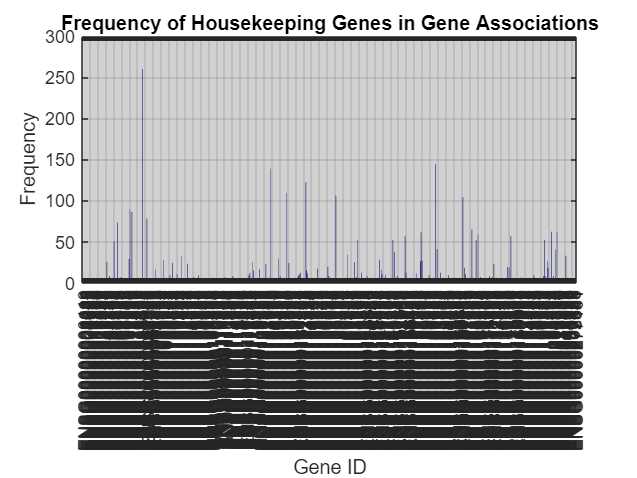


% Plot it 
plotGeneFrequency(geneFreq);